# Conditional Gaussian stocastic simulation with area-to-point kriging (A2PK)

This script show you how to generate stocastic fine-scale realization conditioned to a coarse-scale image AND some fine-scale hard data using area-to-point kriging and conditioning kriging.

See ... for the basic unconditional simulation. This script gives less explaination and assume that the reader is familiar with the unconditional simulation.

addpath('./FastGaussianSimulation');
addpath('./functions');

## Generation of the synthetic data

This is exactly similaire to the first section of ...

covar.model='exponential'; covar.range=[10 10]; covar.var=1; covar.azimuth=0;
covar = covarIni(covar);
z.x=1:50;
z.y=1:50;
[z.X,z.Y] = meshgrid(z.x, z.y);
z.nxy = numel(z.X);
z.s = [numel(z.x) numel(z.y)];
z.true = FGS(z, covar);
z.true = z.true{1};
Z.dx=4; Z.dy=4;
Z.x = mean(z.x(1:Z.dx)):Z.dx:mean(z.x(end-Z.dx+1:end));
Z.y = mean(z.y(1:Z.dy)):Z.dy:mean(z.y(end-Z.dy+1:end));
[Z.X,Z.Y] = meshgrid(Z.x, Z.y);
G = zeros(numel(Z.X),z.nxy);
[~,id] = min(bsxfun(@minus,Z.X(:), z.X(:)').^2 + bsxfun(@minus, Z.Y(:), z.Y(:)').^2);
G(sub2ind(size(G), id, 1:z.nxy)) = 1/(Z.dx*Z.dy);

Z.true = reshape(G * z.true(:), numel(Z.y), numel(Z.x));

## Sample zt at a few location

We sample the value on the true field with the function `sampling_pt`, which has 2 methods possible of sampling (3rd arguement), either as vertical line with `1` or as random `2`. The 4th arguement is the number of samples or lines to sample

z.pt = sampling_pt(z,z.true,2,5);

## Plot

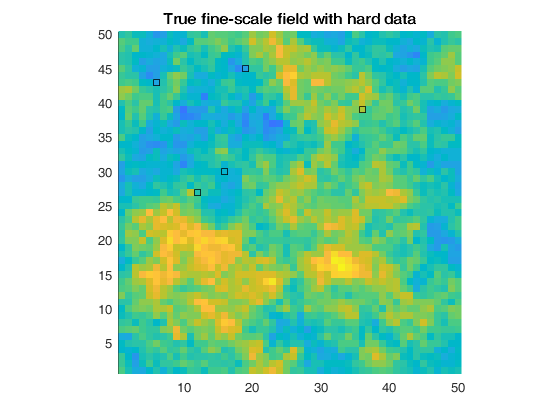

c_axis=[-3 3];%c_axis=[ min(z.true(:)) max(z.true(:))];
figure; hold on;
imagesc(z.x, z.y, z.true);
scatter(z.pt.x,z.pt.y,[],z.pt.d,'s','filled','MarkerEdgeColor','k'); title('True fine-scale field with hard data'); 
caxis(c_axis); axis tight equal;

## Kriging prediction

Czz = covar.g(squareform(pdist([z.X(:) z.Y(:)]*covar.cx)));
CzZ = Czz * G';
CZZ = G * CzZ;

In addition to the covariance between/among the fine and coarse scale, we also need now the covariance with the hard data. 

Czptzpt = Czz(z.pt.id,z.pt.id);
Czzpt = Czz(:,z.pt.id);
CZzpt = CzZ(z.pt.id,:);

The kriging system can then be built and the kriging weight computed

CCa = [ CZZ CZzpt' ; CZzpt Czptzpt ];
CCb = [ CzZ' ; Czzpt' ];

W = (CCa \ CCb)';
z.krig = reshape( W * [Z.true(:) ; z.pt.d(:)], z.s(2),z.s(1));

## Plot

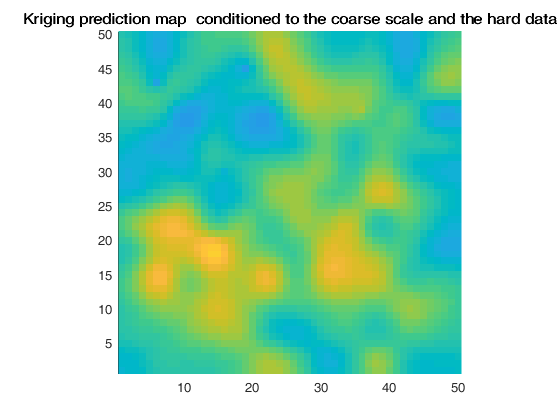

imagesc(z.x, z.y, z.krig); caxis(c_axis); title('Kriging prediction map  conditioned to the coarse scale and the hard data');

## Generate conditional realization

z.uncondSim = FGS(z, covar);
z.uncondSim = z.uncondSim{1};
Z.uncondSim = reshape(G * z.uncondSim(:), numel(Z.y), numel(Z.x));
z.krigSim = reshape( W * [Z.uncondSim(:); z.true(z.pt.id(:))], z.s(2),z.s(1));
z.condSim = z.krig + (z.uncondSim - z.krigSim);
Z.condSim = reshape(G * z.condSim(:), numel(Z.y), numel(Z.x));

## Plot

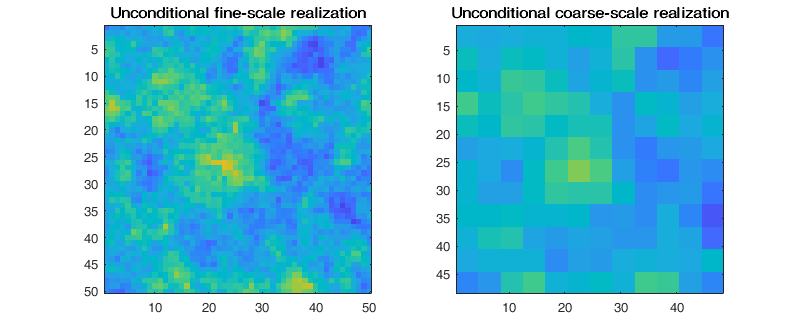

figure('pos',[0 0 800 330])
subplot(1,2,1); imagesc(z.x, z.y, z.uncondSim); caxis(c_axis); title('Unconditional fine-scale realization');
subplot(1,2,2); imagesc(Z.x, Z.y, Z.uncondSim); caxis(c_axis); title('Unconditional coarse-scale realization');

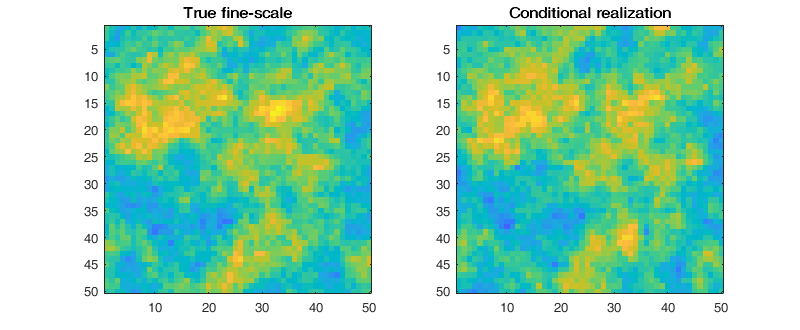

figure('pos',[0 0 800 330])
subplot(1,2,1); imagesc(z.x, z.y, z.true); caxis(c_axis); title('True fine-scale');
subplot(1,2,2);imagesc(z.x, z.y, z.condSim); caxis(c_axis); title('Conditional realization');

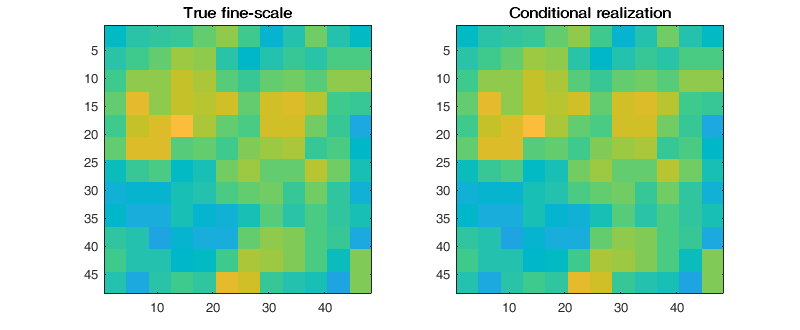

figure('pos',[0 0 800 330])
subplot(1,2,1); imagesc(Z.x, Z.y, Z.true); caxis(c_axis); title('True fine-scale');
subplot(1,2,2);imagesc(Z.x, Z.y, Z.condSim); caxis(c_axis); title('Conditional realization');

## Analysis of the realization

- Histogram and Variogram

*TO BE DONE*